# TP Rheologie des Milleux Continus

% Pedro Henrique Suruagy Perrusi

clear all;
close all;

## Question 1 (Fit des donnees)

% Ajouter bruit ?
add_bruit = true;
snr = 0; %dB
% Generation des donnees
x = 1 : 10;
donnes_exp = 2*x + 5;
if (add_bruit)
    donnes_exp = awgn(donnes_exp, snr);
end
% affichage initialle
plot(x , donnes_exp, 'o'); hold on;

% Methode 1:  partir d'outil basic fitting..
% au cliauer en tools -> basic fitting -> lineaire
% on obtient y = p1*x + p2;
%   p1 = 2; p2 = 5; norm_residus = 7.9441e-15
disp('Parametres estimees par figure outils')

Parametres estimees par figure outils


disp('p1 = 2; p2 = 5')

p1 = 2; p2 = 5


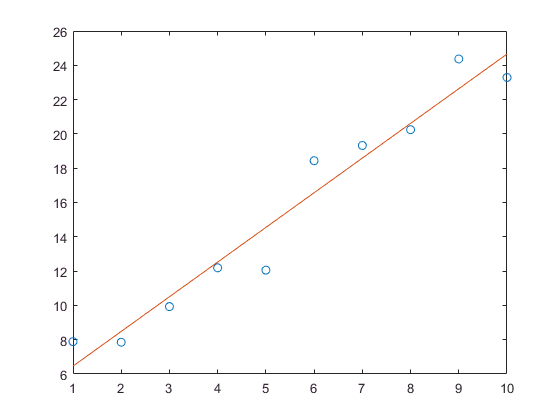


% Methode 2: a partir de polyfit
degree = 1;
p = polyfit(x, donnes_exp, degree);
% donc, on peut estimer
donnes_estimees2 = p(1) * x + p(2);
% plot estimes
plot(x, donnes_estimees2);

disp('Parametres estimees par polyfit')

Parametres estimees par polyfit


disp(p)

    2.0217    4.4393




% Methode 3: a partir de fminsearch
% generate le vecteur entre de fminsearch
init_set = [1 1]; % initial values for p1 and p2
G_opt = fminsearch(@(experimental_set) optim_lineaire(donnes_exp,x,experimental_set), init_set);
disp('Parametres estimees par fminsearch')

Parametres estimees par fminsearch


disp(G_opt)

    2.0217    4.4393



## Question 2 (Tritement des resultats du capteur)

% caracteristiques
epaisseur_i = 0.007; %m
diametre = 0.010; %m
% la machine nous fourni des donnees de deplacement, en mm , et force, en
% mN
deplacement = [0 0.35 0.7 1.05 1.4 1.75 2.1 2.45 2.8]./1000;
force = [0 38 85 126 180 252 349 503 895]./1000;
% on calcule la deformation alpha1
alpha = (epaisseur_i + deplacement)/epaisseur_i;
disp('Strain alpha 1:')

Strain alpha 1:


disp(alpha)

    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000



% on calcule le stress
t1 = force./(pi*diametre^2/4);
% note que pour une deformation uniaxiale la contrainte vrai est
sigma = t1 .* alpha;
disp('Engineering stress')

Engineering stress


disp(t1)

   1.0e+04 *

         0    0.0484    0.1082    0.1604    0.2292    0.3209    0.4444    0.6404    1.1395



disp('Real stress')

Real stress


disp(sigma)

   1.0e+04 *

         0    0.0508    0.1190    0.1845    0.2750    0.4011    0.5777    0.8646    1.5954



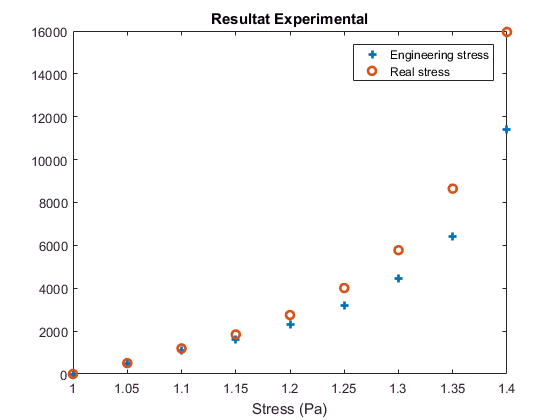


% plot les donnees
figure
plot(alpha, t1, '+', 'LineWidth', 2);hold on;
plot(alpha, sigma, 'o', 'LineWidth', 2); hold off;
legend('Engineering stress', 'Real stress');
xlabel('Alpha (Lambda)')
xlabel('Stress (Pa)')
title('Resultat Experimental')

## Question 3 (Fit par des modeles de deformation)

modele neo hookean 1/2*G(alpha1^2 + alpha2^2 + alpha3^2 -3) = G*(alpha.^2 - 1/alpha)

G_i = 1; % initial values for G
G_opt = fminsearch(@(G) optim_neo_hookean(sigma,alpha,G), G_i);
disp('Neo Hook : Parametres estimees pour G (Pa)')

Neo Hook : Parametres estimees pour G (Pa)


disp(G_opt)

   8.3808e+03




% modele Mooney-Rivelin
C_i = [100 100];
C_optm = fminsearch(@(C) optim_mooney_rivelin(sigma,alpha,C), C_i);
disp('Mooney: Parametres estimees pour C (Pa)')

Mooney: Parametres estimees pour C (Pa)


disp(C_optm)

   1.0e+04 *

    2.5703   -2.8268



disp('Validation du resultat:')

Validation du resultat:


disp('abs(C(2)-C(1)) doit etre en tour de 2.5KPa ')

abs(C(2)-C(1)) doit etre en tour de 2.5KPa 


disp(abs(C_optm(2))-abs(C_optm(1)))

   2.5653e+03




% modele d'ogden
O_i = [1 1; 100 100];
O_optm = fminsearch(@(O) optim_ogden(sigma,alpha,O), O_i);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 186715.971335 



disp('Ogden: Parametres estimees pour O (Pa)')

Ogden: Parametres estimees pour O (Pa)


disp(O_optm)

   1.0e+03 *

    0.0240    0.0026
    0.0033    3.0336



disp('Validation du resultat:')

Validation du resultat:


disp('sum(u * a) doit etre dordre de KPa ')

sum(u * a) doit etre dordre de KPa 


disp(sum(O_optm(1,:).*O_optm(2,:)))

   7.9148e+03




% modele de Langevin
L_i = [10000 1 0.0001];
L_optm = fminsearch(@(L) optim_langevin(sigma,alpha,L), L_i);
disp('Langevin: Parametres estimees pour L (Pa)')

Langevin: Parametres estimees pour L (Pa)


disp(L_optm)

    2.5726    0.8753    0.0002



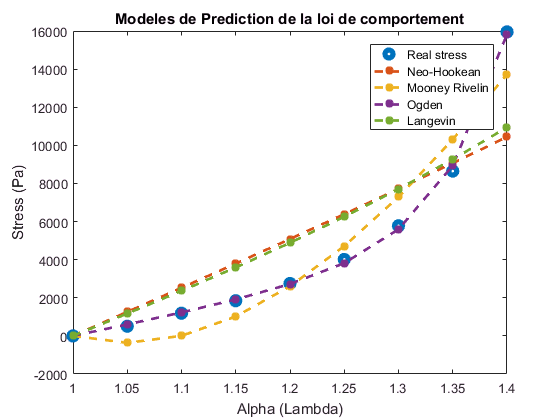

%     disp('Validation du resultat:')
%     disp('sum(u * a) doit etre dordre de KPa ')
%     disp(sum(O_optm(1,:).*O_optm(2,:)))

% plot les donnees
figure
plot(alpha, sigma, 'o', 'LineWidth', 4);hold on;
plot(alpha, neo_hookean(alpha, G_opt), '*--', 'LineWidth', 2);
plot(alpha, mooney_rivelin(alpha, C_optm), '*--', 'LineWidth', 2);
plot(alpha, ogden(alpha, O_optm), '*--', 'LineWidth', 2);
plot(alpha, langevin(alpha, L_optm), '*--', 'LineWidth', 2);hold off;
legend('Real stress', 'Neo-Hookean', 'Mooney Rivelin','Ogden', 'Langevin');
xlabel('Alpha (Lambda)')
ylabel('Stress (Pa)')
title('Modeles de Prediction de la loi de comportement')

**Conclusion**

Pour le jeu de donéés de cet experiment, les modeles d'Ogden et Mooney Rivelin sont les meilleures pour décrire le comportement du material étudie